# Paper2 Fig5: Activity maps

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
%DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2

addpath(DataFolder2)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

close all

## 2. Load Data sets

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
AngAll = 0:7.5:90;

first define figure

Fig5 = figure("Name",'NESSs','units','normalized','outerposition',[0,0,0.6,0.45]);
Panel1 = 2; Panel2 = 7;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.03 .03],[.08 .08],[.10 .10]);
Caxe = [5 35; 30 110];

get correct angle an rotation: Fig 5A

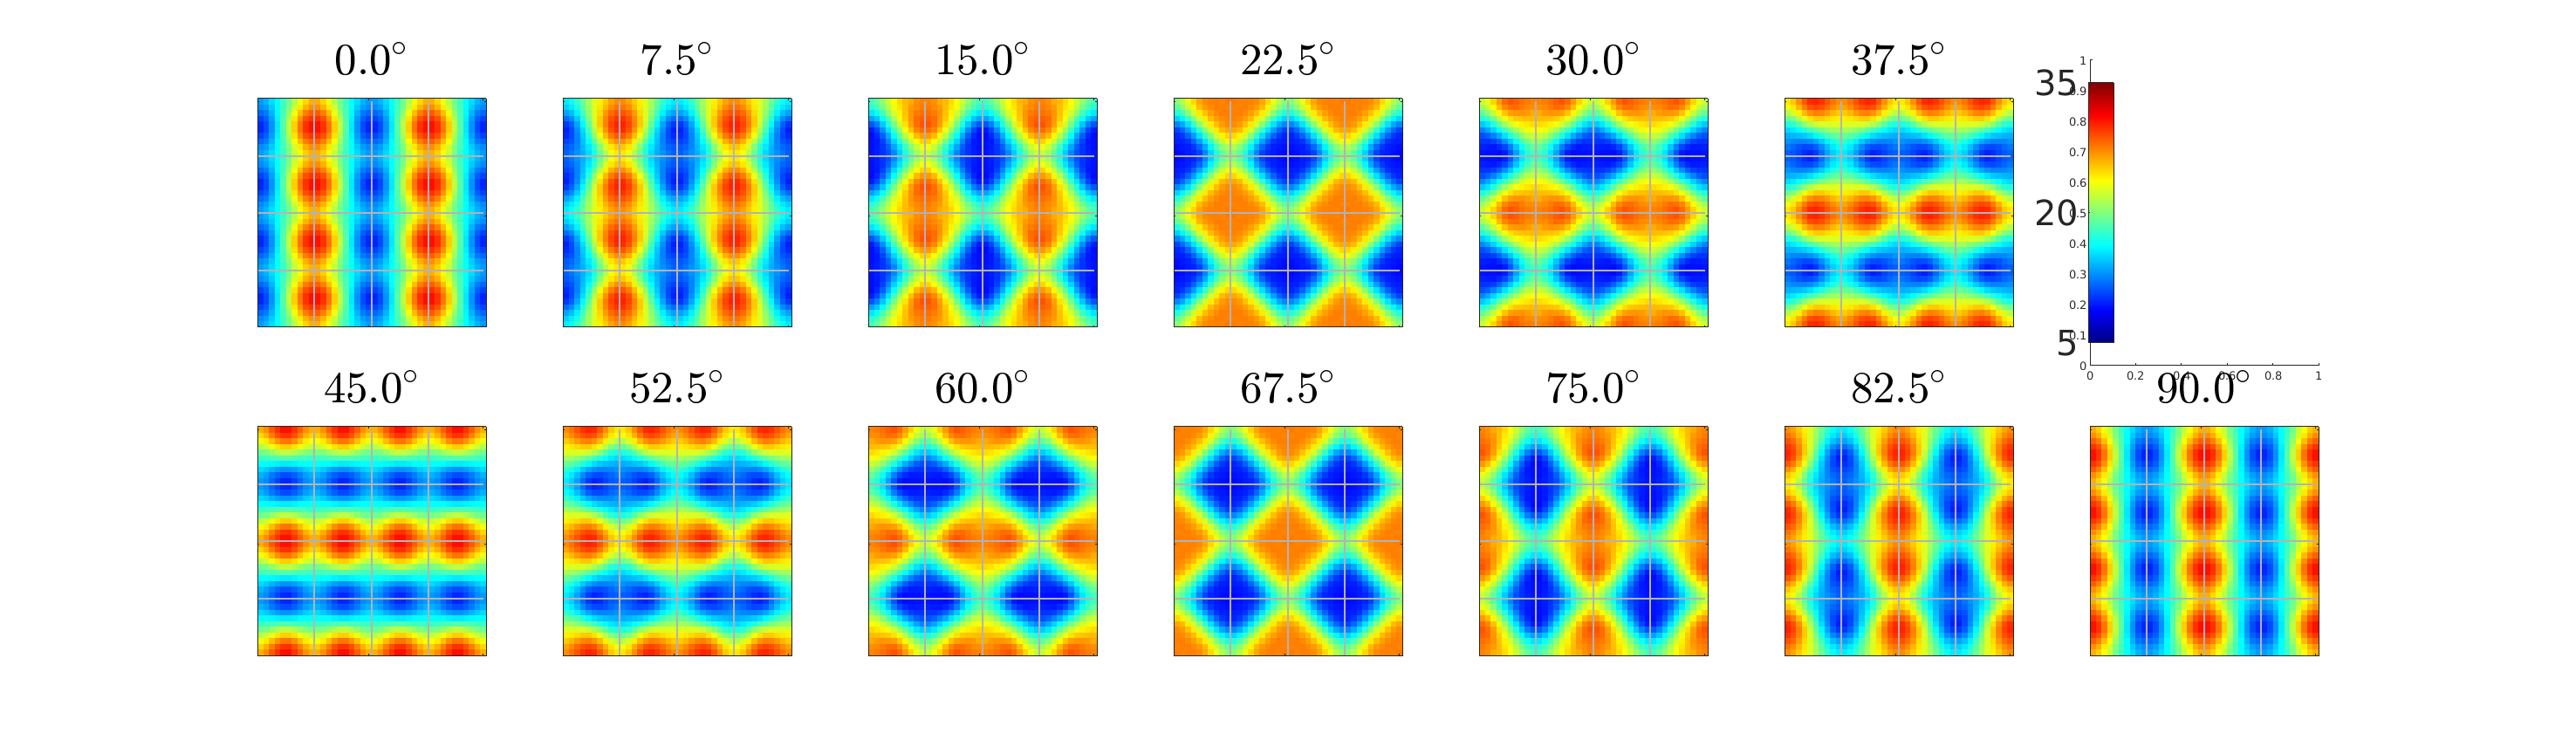

for AngInd = 1:length(AngAll)
    AngleInpt = AngAll(AngInd);% has to be multiples of 7.5
    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end
    
    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
    
    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
    
    
    N_HCOut = 4;
    PixNumOut = N_HCOut*NPixX*N_HCOut*NPixY;
    
    PlotUse = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang%s.mat',AngPrint)],'LDEEquv');
    Patt = PlotUse.LDEEquv;
    Patt = HCRot(Patt,RotInd,N_HCOut,NPixX,NPixY,MirInd);
    
    if AngInd < 7
        axes(ha(AngInd)); % E panel
    else
        axes(ha(AngInd+1));
    end
    
    ShowField(...
        Patt.S*(1-CplxR)+Patt.C*CplxR,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        '', Caxe(1,:)) % last input may catgorized cbar: ,, [5 60]
    title(sprintf('$$%.1f^\\circ$$',AngleInpt),'Interpreter',"latex",'fontsize',35)
    set(gca,'fontsize',35)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    colorbar off
    ax1 = gca;
    
%     if AngInd == 1
%         axes(ha(15));
%         ShowField(...
%             Patt.S*(1-CplxR)+Patt.C*CplxR,...
%             1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
%             sprintf('%.1f deg',AngleInpt), Caxe(1,:)) % last input may catgorized cbar: ,, [5 60]
%         set(gca,'fontsize',13)
%         set(gca,'YTickLabel',[]);
%         set(gca,'XTickLabel',[]);
%         colorbar off
%     end
    
    if AngInd == 6
        Pos1 = get(ax1,'Position');
    end
    
end

cbr1 = colorbar(ax1, 'Position', [Pos1(1)+Pos1(3)+0.05  Pos1(2)+0.03  0.01  Pos1(4)-0.06]);
caxis(Caxe(1,:))
set(cbr1,'YTick',5:15:35,'FontSize',30)

Fig 5C

% for AngInd = 1:length(AngAll)
%     AngleInpt = AngAll(AngInd);% has to be multiples of 7.5
%     RotInd = floor(AngleInpt/45); % 0-3
%     MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
%     switch MirInd % find the corresponding source
%         case 0
%             AngSource = mod(AngleInpt,45);
%         case 1
%             AngSource = mod(-AngleInpt,45);
%     end
%     
%     % Use the source, decide which response function for angle should I use
%     AngFuncCtgrCdid = 0:7.5:22.5;
%     [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
%     
%     AngPrint = AngleList{AngFuncCtgr};
%     Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
%     
%     
%     N_HCOut = 4;
%     PixNumOut = N_HCOut*NPixX*N_HCOut*NPixY;
%     
%     PlotUse = load([DataFolder2 sprintf('LDETracesV4D2_NewSmear_ang%s.mat',AngPrint)],'LDEEquv');
%     Patt = PlotUse.LDEEquv;
%     Patt = HCRot(Patt,RotInd,N_HCOut,NPixX,NPixY,MirInd);
%     
%     if AngInd < 7
%         subplot(7,7,35+AngInd) % E panel
%     else
%         subplot(7,7,36+AngInd);
%     end
%     
%     ShowField(...
%         Patt.S*(1-CplxR)+Patt.C*CplxR,...
%         1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
%         '', Caxe(1,:)) % last input may catgorized cbar: ,, [5 60]
%     title(sprintf('$$%.1f^\\circ$$',AngleInpt),'Interpreter',"latex")
% 
%     set(gca,'fontsize',25)
%     set(gca,'YTickLabel',[]);
%     set(gca,'XTickLabel',[]);
%     colorbar off
%     axis([NPixX+.5 2*NPixX+.5 NPixX+.5 2*NPixY+.5])
%     
% end

Save figures

FigName1 = sprintf('Figure5ADraft');
savefig(Fig5,[FigurePaperPath FigName1 '.fig']);


Print Figs

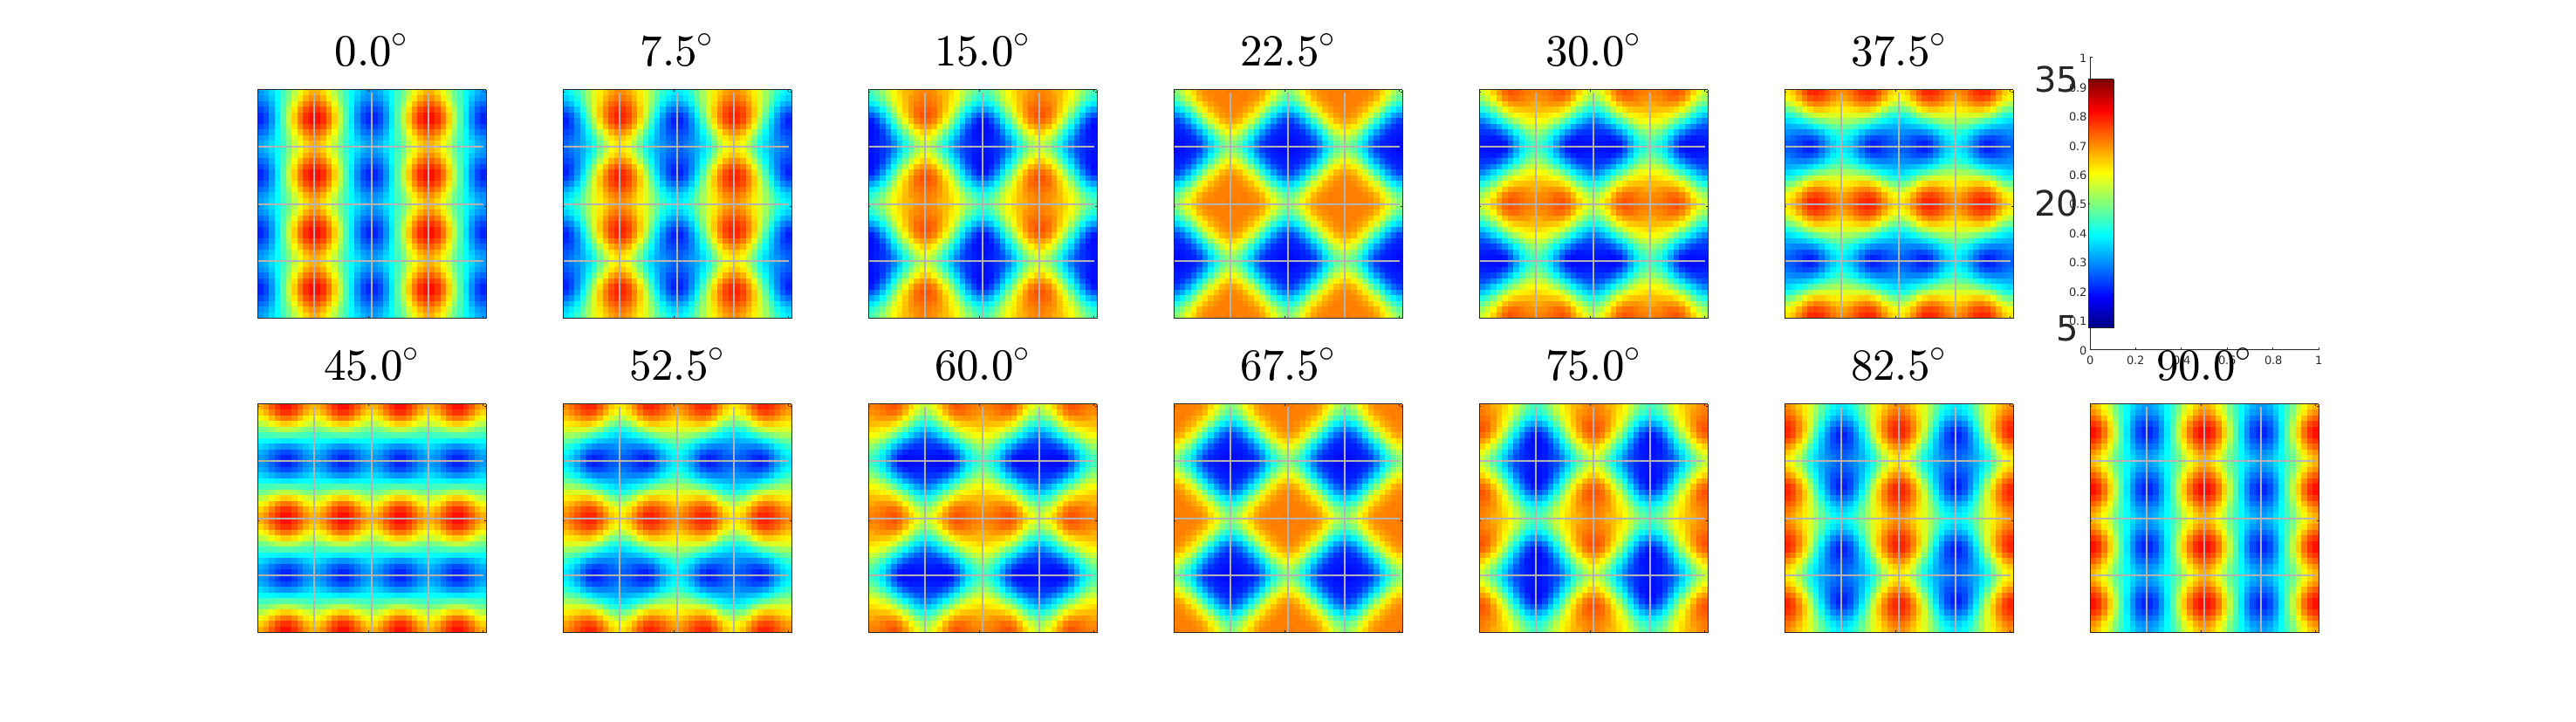

Fig5.PaperUnits = 'inches';
Fig5.PaperSize = [20,10.5];
Fig5.PaperOrientation = "landscape";
exportgraphics(Fig5,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)